% Get labels for each image.
load trainingHoGData.mat;


 
rng default
pool = parpool; % Invoke workers

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


options = statset('UseParallel',true);
classifier = fitcecoc(hogFeatures, trainingLabels,'Options',options);

testingFolder = 'C:\Users\User\Google Drive\Greenstand\SVM\Testing';

imds = imageDatastore(testingFolder,'IncludeSubfolders',true,'LabelSource','foldernames');

imdsAug = augmentedImageDatastore([300,300],imds,'OutputSizeMode','centercrop' );

 

hogTestFeatures = zeros(length(imds.Files),length(hogFeatures));

for i = 1:length(imds.Files)
    try
     dataTable = readByIndex(imdsAug,i);
     img = dataTable{1,1}{1};
     img = SegmentGreenWithOtsu(img);   

    [testFeatures , ~] = extHoGFeatures(img);
    hogTestFeatures(i,:) = testFeatures;
    catch ME
        disp(ME);
    end
end

     

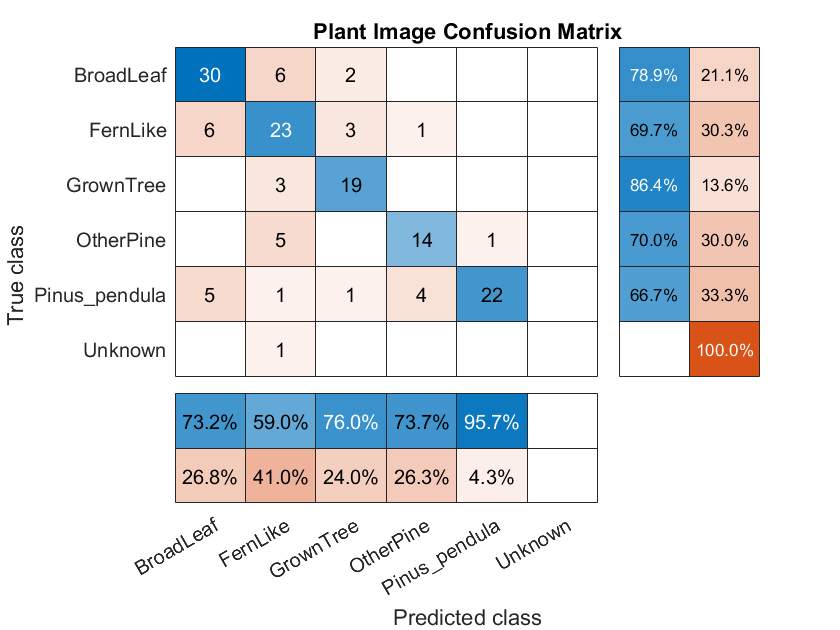

% Make class predictions using the test features.
predictedLabels = predict(classifier, hogTestFeatures);
testLabels = imds.Labels;
% Tabulate the results using a confusion matrix.
[confMat,order] = confusionmat(testLabels, predictedLabels);

figure
cm = confusionchart(confMat,order);

cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'Plant Image Confusion Matrix';